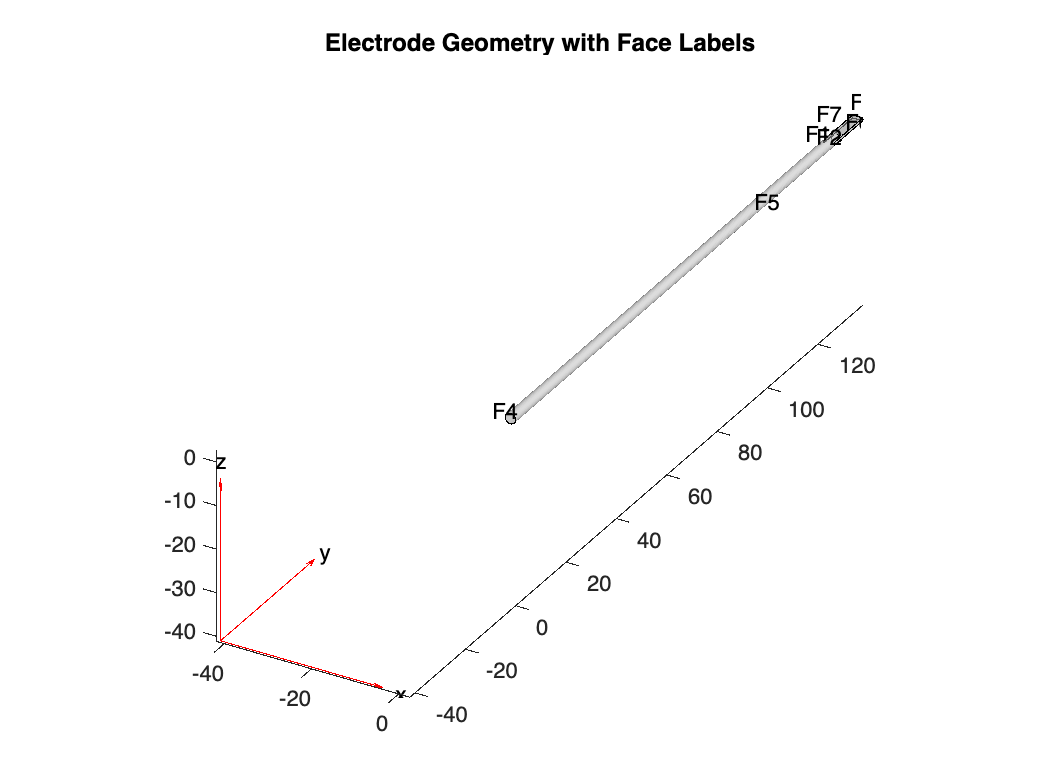


% Load geometry and create structural model
model = femodel(AnalysisType="structuralStatic", Geometry="electrode_MATLAB_test.STL");

% Visualize geometry with face labels
figure
ylim([0 inf])
pdegplot(model, FaceLabels="on", FaceAlpha=0.5)
title("Electrode Geometry with Face Labels")


% Generate mesh
model = generateMesh(model, Hmax=0.5);

Error using fegeometry/generateMesh
Meshing failed for Hmax of 0.5 and Hmin of 0.25. Try adjusting Hmax and Hmin.

Error in femodel/generateMesh (line 306)
            obj.Geometry_I = generateMesh(obj.Geometry,nvpairs{:});


% Define material properties (example: nickel alloy)
E = 227E9;       % Young's modulus in Pa
nu = 0.27;       % Poisson's ratio
CTE = 12.7E-6;   % Coefficient of thermal expansion in 1/K
model.MaterialProperties = materialProperties(YoungsModulus=E, PoissonsRatio=nu, CTE=CTE);

% Apply structural boundary condition (adjust face ID as needed)
model.FaceBC(4) = faceBC(Constraint="fixed");

% Switch to thermal analysis
model.AnalysisType = "thermalSteady";

% Define thermal conductivity
kapp = 11.5;  % W/m/K
model.MaterialProperties = materialProperties(ThermalConductivity=kapp);

% Apply thermal boundary conditions
model.FaceLoad(1) = faceLoad(ConvectionCoefficient=25, AmbientTemperature=310);  % Left
model.FaceLoad(2) = faceLoad(ConvectionCoefficient=25, AmbientTemperature=310);  % Right
model.FaceLoad(3) = faceLoad(ConvectionCoefficient=50, AmbientTemperature=350);  % Distal tip
model.FaceLoad(4) = faceLoad(ConvectionCoefficient=20, AmbientTemperature=300);  % Proximal shaft
model.FaceLoad(5) = faceLoad(ConvectionCoefficient=15, AmbientTemperature=295);  % Shaft face
model.FaceLoad(6) = faceLoad(ConvectionCoefficient=30, AmbientTemperature=320);  % Bottom
model.FaceLoad(7) = faceLoad(ConvectionCoefficient=30, AmbientTemperature=320);  % Top


% Solve thermal problem
Rt = solve(model);


% Plot temperature distribution
figure
pdeplot3D(Rt.Mesh, ColorMapData=Rt.Temperature)
title("Temperature Distribution")
view([130,-20])

% Switch back to structural analysis for thermal stress
model.AnalysisType = "structuralStatic";
model.MaterialProperties = materialProperties(YoungsModulus=E, PoissonsRatio=nu, CTE=CTE);
model.ReferenceTemperature = 300;
model.CellLoad = cellLoad(Temperature=Rt);
model.FaceBC(3) = faceBC(Constraint="fixed");

% Solve thermal stress problem
Rts = solve(model);

% Plot thermal stress and deformation
figure
pdeplot3D(Rts.Mesh, ColorMapData=Rts.VonMisesStress,Deformation=Rts.Displacement, DeformationScaleFactor=100)
title("Thermal Stress and Deformation")
clim([0, 200e6])
view([116,25])

% Evaluate tip displacement
maxDisplacement = max(Rts.Displacement.Magnitude);
disp("Maximum tip displacement due to thermal stress:")
disp(maxDisplacement)
